Разные полезные функции над матрицами и векторами

x = 1:9;
matr = reshape(x,3,3)'

matr =      1     2     3
     4     5     6
     7     8     9


x = [1, 1.5, 2, 2.1, 2.2, 2.5];
t = [0.1, 0.5, 1.5, 3, 4, 5];
dt = diff(t)

dt =     0.4000    1.0000    1.5000    1.0000    1.0000


df = diff(x)./dt

df =     1.2500    0.5000    0.0667    0.1000    0.3000


cx = cumsum(x);
t = cumsum([0.1, dt])

t =     0.1000    0.5000    1.5000    3.0000    4.0000    5.0000


Cell-arrays

C = {[1,2,3], [0,2]; 'abc', "string"}

C = 2×2 cell array
    {[1 2 3]}    {[     0 2]}
    {'abc'  }    {["string"]}


C = {[1,2,3], [0,2]}

C = 1×2 cell array
    {[1 2 3]}    {[0 2]}


cellfun(@max,C)

ans =      3     2


Интегралы-производные

sqr = @(x) x.^2;
sqr(2)

ans = 4

int = integral(sqr,0,2)

int = 2.6667

lin = @(t,x) -x;
t = 0:5;
x0 = 1;
[t,y] = ode45(lin,t,x0)

t =      0
     1
     2
     3
     4
     5


y =     1.0000
    0.3679
    0.1353
    0.0498
    0.0183
    0.0067


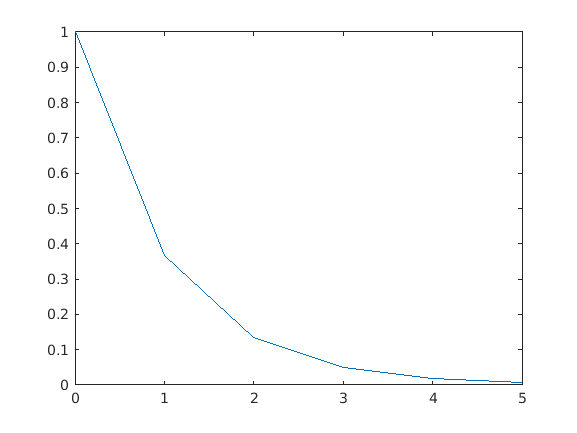

plot(t,y)

Символьные вычисления

syms x y;
expr = x^2 + 2*x*y + y^2

$$expr = x^{2}+2\,x\,y+y^{2}$$

simp = simplify(expr)

$$simp = {\left(x+y\right)}^{2}$$

expr + 2*x*y

$$ans = x^{2}+4\,x\,y+y^{2}$$

subs(expr,[x,y],[1,2])

$$ans = 9$$

expr_derivative = diff(expr,x)

$$expr\_derivative = 2\,x+2\,y$$

expr_simple = x.^2;
char_derivative = ['@(x) ',char(diff(expr_simple))]

char_derivative = '@(x) 2*x'

fun_derivative = eval(char_derivative)

fun_derivative = function_handle with value:
    @(x)2*x


fun_derivative(1)

ans = 2

sym_int = int(expr_simple)

$$sym\_int = \frac{x^{3}}{3}$$

% string to symbolic expression
% str2sym('x+1')